# EEG Artifacts

This script investigates how tACS stimulation artifacts affect EEG/LFP analysis and shows results for FASTR, FBAR, and RBAR algorithms.

## Setup Simulation

First define the stimulation and recording parameters.

startup; % Make sure all toolboxes are on the path

eegDefaults.reproducible              = true;    % Fix the random number generator to get reproducible results

Equipment:

eegDefaults.stimulatorSamplingRate    = 1e3;     % Neuroconn (2 kHz)
eegDefaults.recordingSamplingRate     = 5e3;     % 5kHz
eegDefaults.currentResolution         = 1e-6;    % 1 muA
eegDefaults.highPass                  = 0.01;    % Analog filter of the recording amplifier


Experiment:


eegDefaults.duration                  = 2*60;   % 2 min of data
eegDefaults.tacsFrequency             = 0;
eegDefaults.tacsAmplitude             = 0;
eegDefaults.tdcsMean                  = 0;

Signals. Setting everything except the background to 0.

eegDefaults.additive                  = 100e-6;   % Background Noise stdev
eegDefaults.lfpAmplitude              = 0;
eegDefaults.multiplicative            = 0;
eegDefaults.zAmplitude                = 0;


And setup the base parameters for artifiact removal

arDefaults.slide                     = false;   % No sliding segment
arDefaults.slack                     = 5e-3;    % 5 ms to realign segments
arDefaults.nrSegsPerWindow           = 10;      % 10 segments to average artifact
arDefaults.pcaNr                     = 2;       % First two PC are removed
arDefaults.pcaVarExplained           = Inf;     % Ignore explained variance, always remove 2.
arDefaults.pcaNrSegsPerWindow        = Inf;     % Use all segments (plus the tCS signal; below) to determine basis set.
arDefaults.referenceSegment          = 1;       % Align to first segment
arDefaults.recordingSamplingRate      = eegDefaults.recordingSamplingRate; % Match to the recording
arDefaults.segmentDuration          = 3;


## Recovering the neural background with FASTR

Create the artSim object using the default parameters defined above, then add tACS to the simulation 

eeg                   = artSim(eegDefaults);
eeg.tacsAmplitude     = 1e-3;    % 1 mA -> 1 mV artifact
eeg.tacsFrequency     = 10;      % 10 Hz


First, investigate the FASTR algorithm (Niazy et al.). Match the artificat removal parameters to the data

ar                          = arDefaults;
ar.tacsFrequency            = eeg.tacsFrequency;


Generate figures

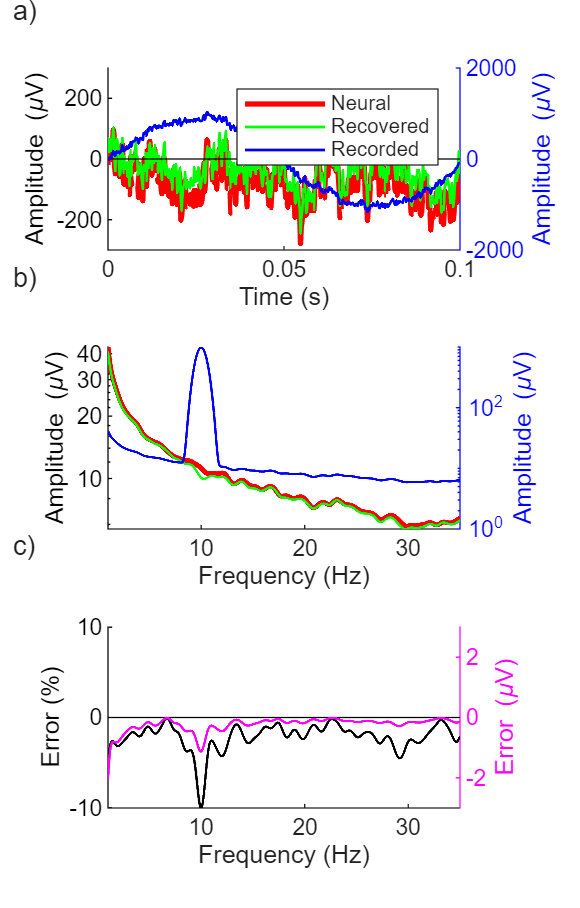

Allocating memory...


ans = 0.0085


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.97 rmse = 16/100 muV ae = 2.2%)


[~,axs] = fig('Name','Fig2','nrCols',1,'height',12,'nrRows',3,'byColumn',false);

simPlotEEG(eeg,ar,'FASTR',axs=axs);

Note that the Neural ground truth and the Recovered signals are generally small and show on the left y-axis. The recorded signal, which includes the artifact, is typically orders of magnitude larger - this graph shows it (blue) on the right y-axis. The figure shows that the recovered signal qualitatively matches the neural signal (green vs.red), but a  closer look , expressing errors as a percentage of the neural signal show substantial underestimation of the neural signal not only near the tACS frequency, but across the entire spectrum. 

The low-resolution spectral analysis hides some important detals. Rerun it now with 0.1 Hz frequency resolution:

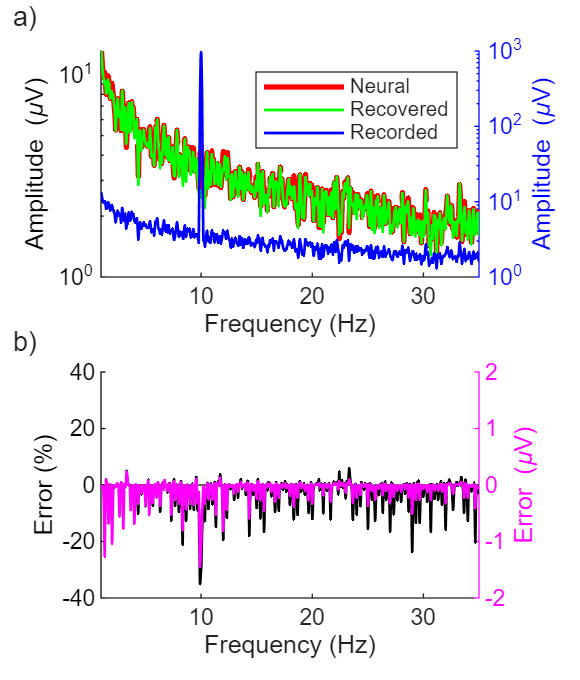

Allocating memory...


ans = 0.0085


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 0 sec.
FASTR (r=0.97 rmse = 16/100 muV ae = 2.8%)


[~,axs] = fig('Name','Fig3','paperCols',1,'height',9,'nrRows',2,'byColumn',false);

simPlotEEG(eeg,ar,'FASTR',freqRes =0.1,axs=[gobjects(1) axs']);

This shows the clear comb artifact that repeats at `o.tacsFrequency/o.nrCycles`, here 10/30 = 0.33 Hz.

## Recovering neural signals and background

Next, we *add* a neural signal in the form of an LFP/EEG signal that peaks at 32 hz, with some spectral spread around that:

eeg.lfpFrequency              = 32;        % Simulated oscillation peak frequency
eeg.lfpAmplitude              = 100e-6;    % Oscillation peak amplitude
eeg.lfpPeakWidth              = 1;         % Oscillation bandwidth.


Generate two figures, one for the time course, one for the error spectrum.

[~,axs4] = fig('Name','Fig4','paperCols',1,'height',10,'nrRows',3,'nrCols',1,'byColumn',false);
[~,axs5] = fig('Name','Fig5','paperCols',2,'height',5,'nrRows',1,'nrCols',3,'byColumn',false);

### FASTR


simPlotEEG(eeg,ar,'FASTR',freqRes =0.1,axs=[axs4(1) gobjects(1) axs5(1)]);

Allocating memory...


ans = -0.0831


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 0 sec.
FASTR (r=0.97 rmse = 20/100 muV ae = 2.8%)


### FBAR

We continue analyzing the same data, but now with a Fourier based algorithm (FBAR), using the same parameters


simPlotEEG(eeg,ar,'FBAR',freqRes =0.1,axs=[axs4(2) gobjects(1)  axs5(2)]);

FBAR (r=0.99 rmse = 8/100 muV ae = 0.7%)


### RBAR

And a regression based method:

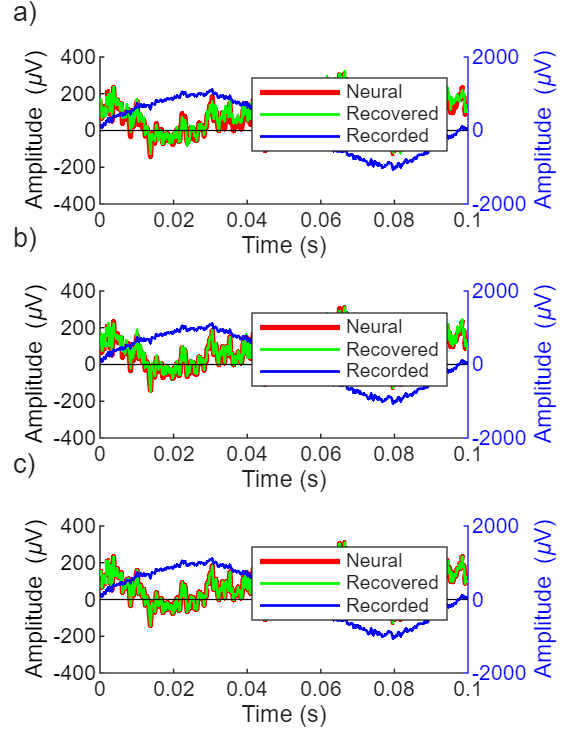

RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)


simPlotEEG(eeg,ar,'RBAR',freqRes =0.1,axs=[axs4(3)  gobjects(1) axs5(3)]);

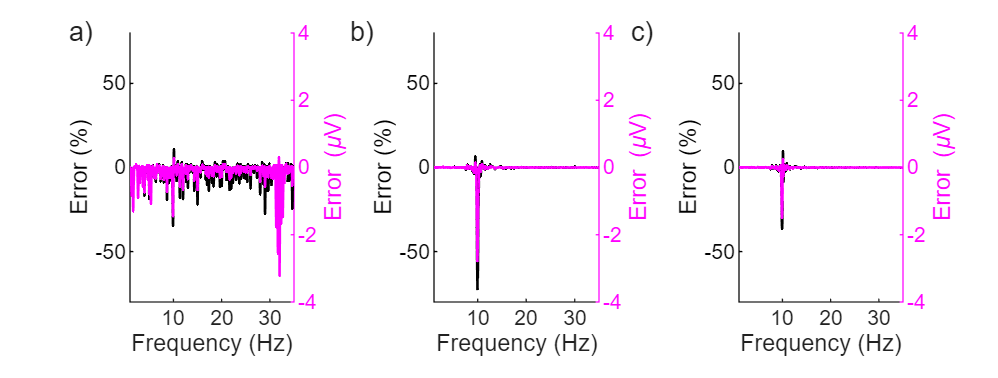


yylinkaxes(axs5); % After plots have been generated - link to get the same scale

This graph shows a 100 ms snippet of the data (red; with the 32 Hz oscillation) and recovered signal (green). Visually, FASTR does not recover the original signal, while FBAR and RBAR do.

This is easier to see in the spectral domain. FASTR has serious persistent artifacts across the spectrum,  FBAR & RBAR perform substantially better, recovering most of the spectrum, except for a band around the tACS frequency.

## Impedance Artifacts tACS

Physiological artifacts such as heartbeats, sweating, or breathing change impedance and interact multiplicatively with the signal. FASTR has a hard time recovering any underlying signals.

Keeping the neural signals from above, but adding an artifact that rhytmically (`o.zFrequency`) changes the impedance sinusoidally, The maximum change in the impedance is defined (as a fraction) by `o.zAmplitude.`

eeg                           = artSim(eegDefaults);      % Start fresh
eeg.tacsAmplitude             = 1e-3;    % 1 mA -> 1 mV artifact
eeg.tacsFrequency             = 10;      % 10 Hz tACS
eeg.lfpFrequency              = 32;        % Simulated oscillation peak frequency
eeg.lfpAmplitude              = 100e-6;    % Oscillation peak amplitude
eeg.lfpPeakWidth              = 1;         % Oscillation bandwidth.

Set ar parameters

ar                          = arDefaults;
ar.tacsFrequency            = eeg.tacsFrequency;


Add physiological arfitacts, first a sinusoidal modulation of the impedance (maybe a reasonable approximation for respiration not so much for a heartbeat):

eeg.zFrequency = 18/60;  % 18 breaths per minute
eeg.zAmplitude = 0.05;  % The artifact changes the impedance by 5%.
[~,axs] = fig('Name','Fig6','paperCols',1.5,'height',9,'nrRows',2,'nrCols',2);
simPlotEEG(eeg,ar,'FASTR',freqRes =0.1,axs=[gobjects(1,2) axs(1)]);

Allocating memory...


ans = -0.0831


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.97 rmse = 21/100 muV ae = 3.8%)


simPlotEEG(eeg,ar,'RBAR',freqRes =0.1,axs=[gobjects(1,2) axs(2)]);

RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)


Next we simulate a impedance modulation that models the ballistic artifacts expected from a heartbeat. This uses an ECG recording and a simple body resonance model to simulate the ballistic impedance changes. See `zHeartbeat.m` for details.

eeg.zFun = @zHeartbeat ;
simPlotEEG(eeg,ar,'FASTR',freqRes =0.1,axs=[gobjects(1,2) axs(3)]);

Allocating memory...


ans = -0.0831


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.97 rmse = 21/100 muV ae = 3.6%)


simPlotEEG(eeg,ar,'RBAR',freqRes =0.1,axs=[gobjects(1,2) axs(4)]);

RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)


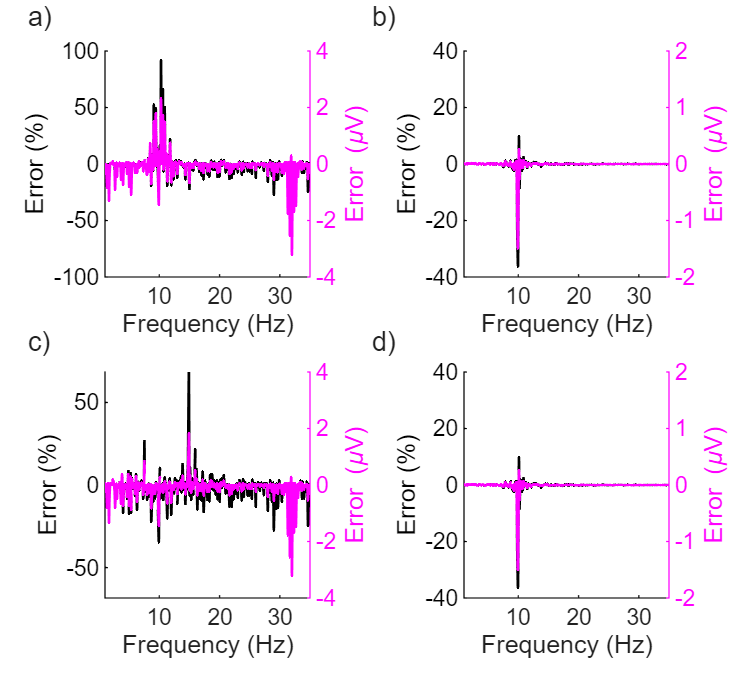

yylinkaxes(axs([2 4]))

Clearly FASTR (a,c) does not recover the neural signal of either sinusoidal/breathing (a) or pulsed/heartbeat (c) impedance artifacts; the multiplicative interactions between physiological artifacts and the true neural signal results in spurious signals across the entire spectrum.  Noury et al explain why this should happen and why there are two prominent peaks in a).  RBAR gets rid of most artifacts and only has a small forbidden zone near the tACS frequency. FBAR (not shown) has the same kind of issues as FASTR.

### Imedance Artifacts tDCS 

As long as recordings exclude the ramp up and ramp down periods, the DC current generated by tDCS does not introduce neural artifacts on its own.  

However, impedance artifacts induced by physiological changes such as heartbeats can result in spurious neural signals. 

eeg                           = artSim(eegDefaults);      % Start fresh
eeg.tdcsMean                  = 1e-3;
eeg.lfpFrequency              = 23;        % Simulated oscillation peak frequency
eeg.lfpAmplitude              = 100e-6;    % Oscillation peak amplitude
eeg.lfpPeakWidth              = 1;         % Oscillation bandwidth.
eeg.duration                  = 120;

eeg.zFun  =  @zHeartbeat;
eeg.zAmplitude = 0.05;  % The artifact changes the impedance by 5%.

ar                          = arDefaults;
ar.recordingSamplingRate    = eeg.recordingSamplingRate;
ar.segmentDuration          = 120;      % Define segments in seconds instead of cycles

[~,axs] = fig('Name','Fig7','paperCols',1.5,'height',9,'nrRows',2,'nrCols',2,'span',{[1, 2 1],[2,1,1],[4,1,1]});

Zoom in on the timecourse near a heartbeat to illustrate the effect. To illustrate the heartbeat effect, remove the background activity.

tlim = [0.35 0.65];
eeg.additive                  = 0;
simPlotEEG(eeg,ar,'NOP',freqRes =1,axs=[axs(1) gobjects(1,2)],tlim=tlim,lineWidth=1);

NOP (r=0.99 rmse = 4/0 muV ae = 84519.2%)


Restore the background activity and show the error spectra.

eeg.additive  =  100e-6;
simPlotEEG(eeg,ar,'NOP',freqRes =1,axs=[gobjects(1,2) axs(2)],tlim=tlim,lineWidth=1);

NOP (r=1.00 rmse = 4/100 muV ae = 0.8%)



simPlotEEG(eeg,ar,'RBAR',freqRes =1,axs=[gobjects(1,2) axs(3)]);

RBAR (r=1.00 rmse = 0/100 muV ae = 0.0%)


yylinkaxes(axs([2 3]));


Overlay the heartbeat for illustration (scaled to the range of the plot).

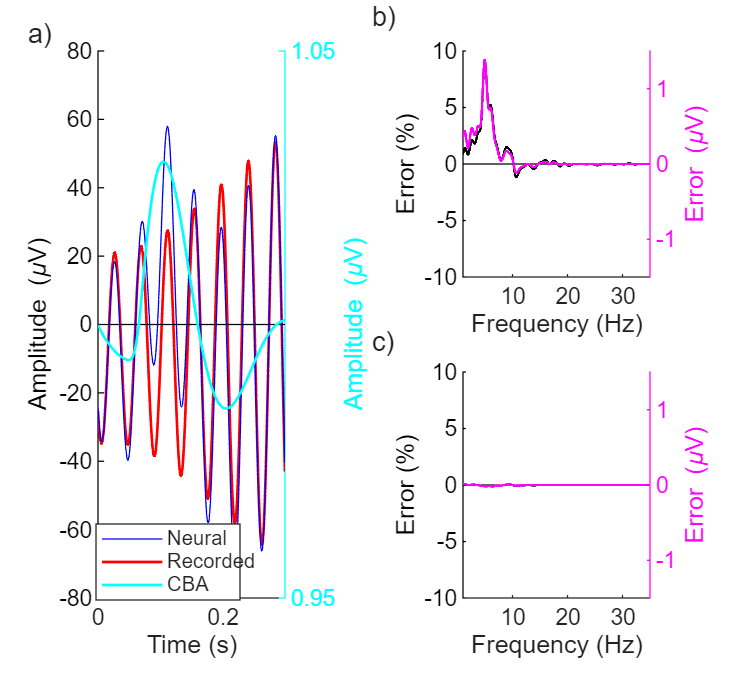

z = eeg.zFun(eeg);
axes(axs(1))

yyaxis right
x =axs(1).Children.XData;
y =axs(1).Children.YData;
cla

stay  = eeg.tSimulate>tlim(1) & eeg.tSimulate < tlim(2);
h = plot(eeg.tSimulate(stay)-min(eeg.tSimulate(stay)),z(stay),'c-','LineWidth',1);
%axs(1).Color = 0.95*ones(1,3);
axs(1).YAxis(2).Color = 'c';
ylim(1+ eeg.zAmplitude*[-1 1])
set(gca,'YTick',1+ eeg.zAmplitude*[-1 1])
yyaxis left
delete(axs(1).Children(2));
plot(x,y,'b-')

legend([axs(1).Children([1 3]);h], 'Neural','Recorded','CBA','Location','none','Position',[0.1283 0.1179 0.1914, 0.1118])